data = readtable('LOB_data.csv');
data

data = 438673×12 table
    MsgType    SeqNumber     Symbol     SourceTime    SymbolSeqnum     OrderID      Price     Volume    Side     FirmID    NumParitySplits    len_firmid
    _______    _________    ________    __________    ____________    __________    ______    ______    _____    ______    _______________    __________

      100        12395      {'AAPL'}     07:00:00           4         1.7733e+16     135.2       5      {'B'}     NaN             0               0     
      100        13035      {'AAPL'}     07:00:49           5         1.7733e+16    141.82     100      {'S'}

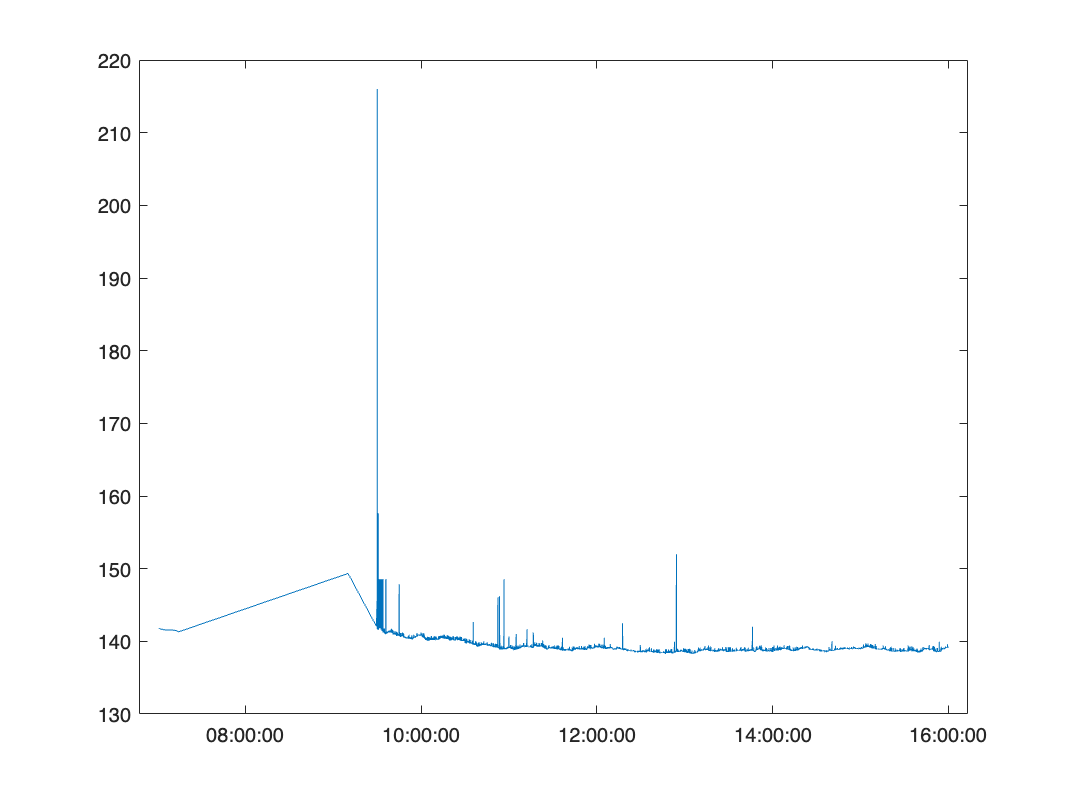


LOB = data(:, {'Price','SourceTime','Volume', 'Side'});

Bid = LOB(strcmp(LOB.Side, 'S'),:);
Ask = LOB(strcmp(LOB.Side, 'B'),:);

% Before data normalization
plt1 = plot(Bid.SourceTime, Bid.Price);

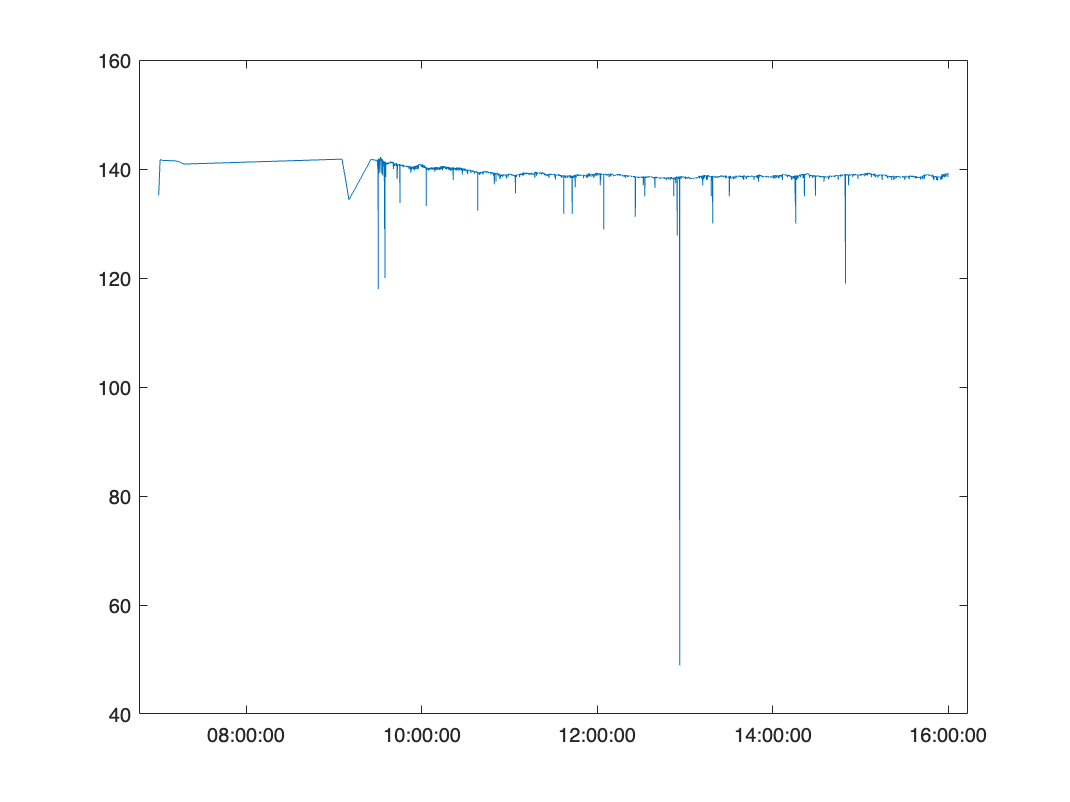

plt2 = plot(Ask.SourceTime, Ask.Price);

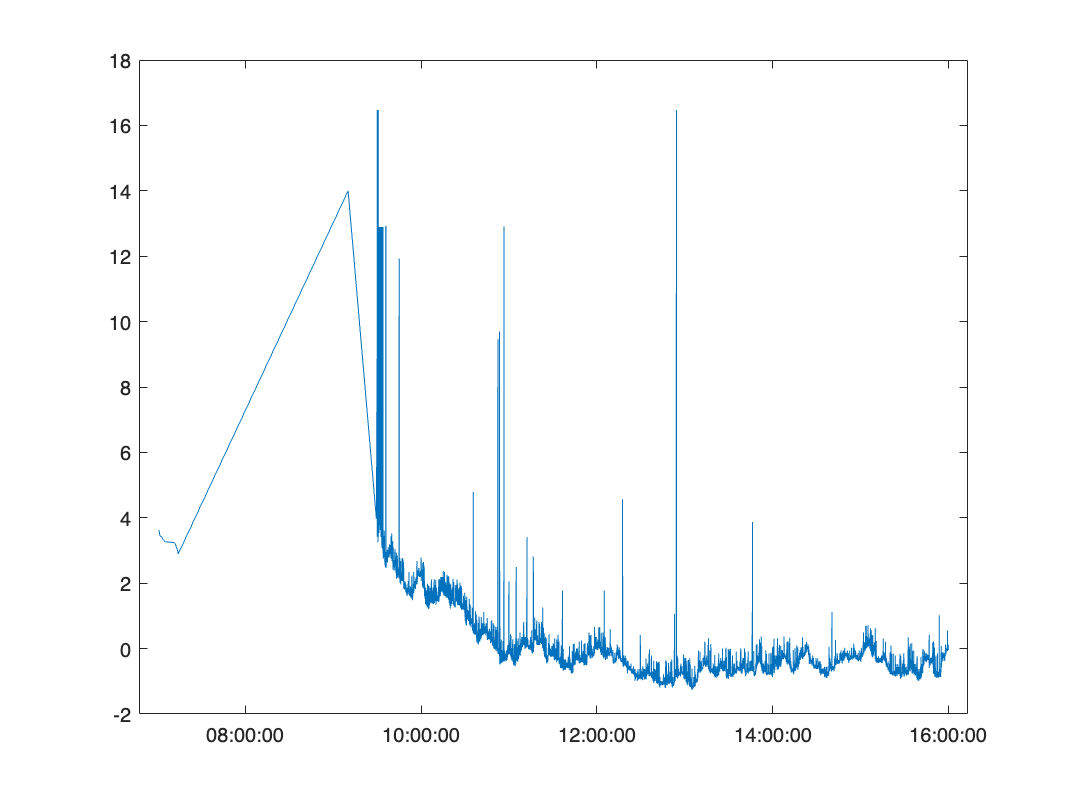

% Data Normalization 
normalizedBid = normalization(Bid);
normalizedAsk = normalization(Ask);

% Before data normalization
plt_1 = plot(normalizedBid.SourceTime, normalizedBid.Price);

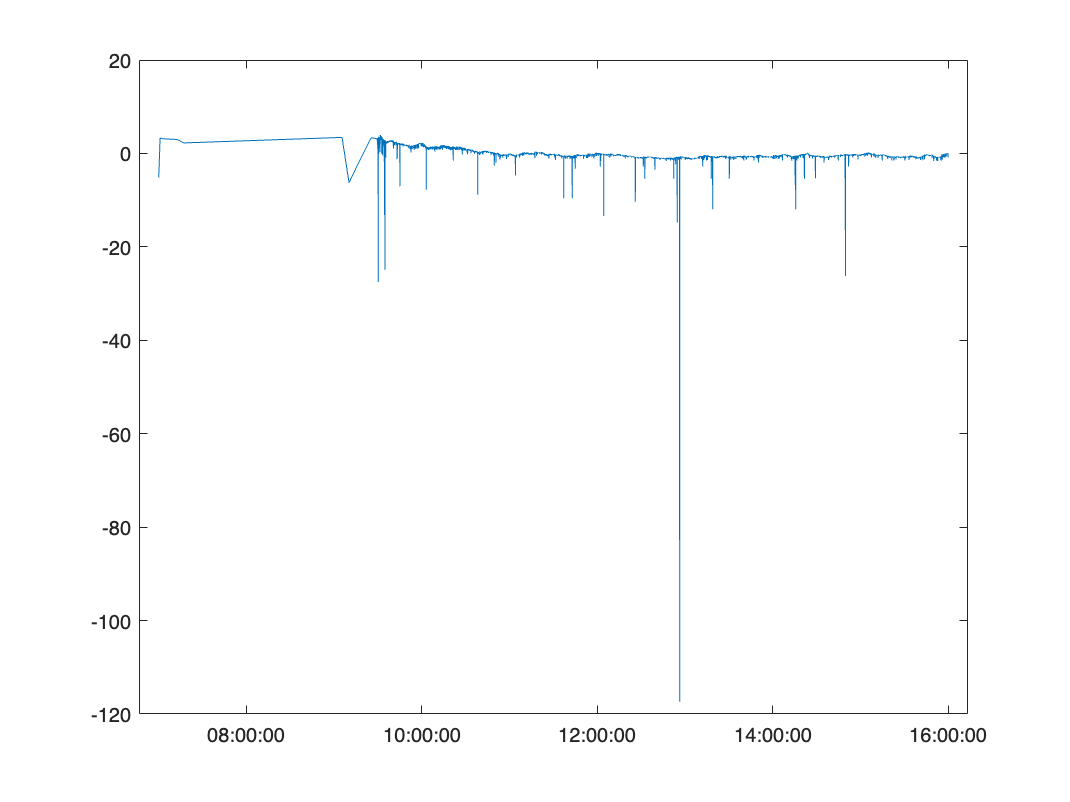

plt_2 = plot(normalizedAsk.SourceTime, normalizedAsk.Price);

% Data Split

function normalizedTable = normalization(data)
 
    % Extract numeric data for normalization
    numericData = table2array(data(:, {'Price', 'Volume'}));

    % Compute Median Absolute Deviation (MAD) for each numeric column
    madValues = mad(numericData);

    % Define a threshold for outliers (e.g., 3 times MAD)
    threshold1 = 280;
    threshold2 = 80;

    % Replace outliers with MAD for 'Price' column
    priceColumn = numericData(:, 1);
    priceColumn(abs(priceColumn) > threshold1 * madValues(1)) = sign(priceColumn(abs(priceColumn) > threshold1 * madValues(1))) * threshold1 * madValues(1);

    % Replace outliers with MAD for 'Volume' column
    volumeColumn = numericData(:, 2);
    volumeColumn(abs(volumeColumn) > threshold2 * madValues(2)) = sign(volumeColumn(abs(volumeColumn) > threshold2 * madValues(2))) * threshold2 * madValues(2);

    % Update the modified columns in the numericData matrix
    numericData(:, 1) = priceColumn;
    numericData(:, 2) = volumeColumn;

    % Z-score normalization
    normalizedData = zscore(numericData);

    % Create a new table with the normalized and outliers-replaced data
    normalizedLOB = array2table(normalizedData, 'VariableNames', {'Price', 'Volume'});

    % Combine the normalized numeric columns with the non-numeric columns
    normalizedTable = [normalizedLOB, data(:, 'SourceTime'), data(:, 'Side')];
end


